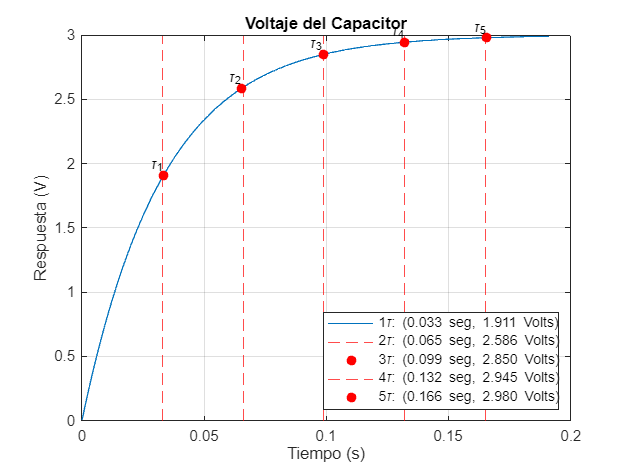

num = [6 * 1/2];
tau = 33 / 1000;
den = [tau 1];

sys = tf(num, den);

[y, t] = step(sys);

plot(t, y);
hold on;

legend_labels = {};

for i = 1:5
    tau_value = i * tau;
    xline(tau_value, '--r');  
    
    [~, idx] = min(abs(t - tau_value));  
    plot(t(idx), y(idx), 'ro', 'MarkerFaceColor', 'r'); 
    
    legend_labels{end+1} = sprintf('%d\\tau: (%0.3f seg, %0.3f Volts)', i, t(idx), y(idx));
    
    text(t(idx), y(idx), sprintf('\\tau_%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end

legend(legend_labels, 'Location', 'southeast');
xlabel('Tiempo (s)');
ylabel('Respuesta (V)');
title('Voltaje del Capacitor');
grid on;
hold off;